% mk_figureS4

% Assess the effect of broadband extraction procedure on model parameters

saveFigure = 1;

## LOAD MODEL PARAMETERS

prmFile = fullfile(dn_ECoG_RootPath, 'data', 'dn_params.mat');
a = load(prmFile);


## EXTRACT PARAMETERS AND PRE-DEFINED PARAMETERS

dn_prms = a.prm.ecog.dn.param;
dn_dt   = a.prm.ecog.dn.bs_bbts;
dn_seed = a.prm.ecog.dn.seed;

ecogPrm = a.prm.ecog.dn;

nSamples = 50; 
dt       = 0.001;
srate    = 1/dt;
trialLth = 1.2;
nTrials  = 210;
tAll     = dt/2 : dt : trialLth * nTrials;
tTrial   = dt/2 : dt : trialLth;
epochs   = reshape(tAll, trialLth/dt, nTrials);

stim = zeros(size(tTrial)); stim(0.2 <= tTrial  & tTrial < 0.7) = 1;

nBoots = size(dn_prms, 1);

summaryMetrics = ecogPrm.summaryMetrics;

## GENERATE DN MODEL PREDICTIONS AND EXTRACT BROADBAND SIGNAL

whiten =     @(x)(x-mean(x(:)))./diff(prctile(x,[.25,.75]))


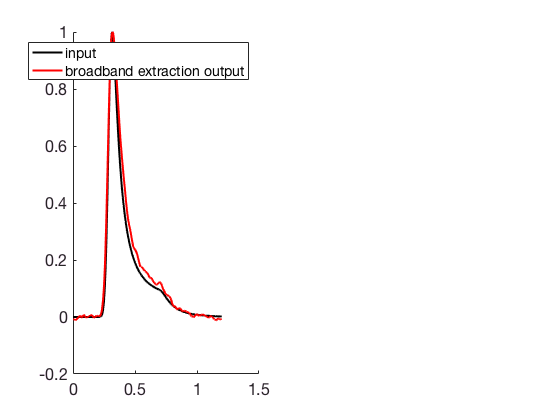

exp_param = [0.1, 0, 0.1, 3, 0.1, 0, 1];
dn_prd    = normMax(dn_DNmodel(exp_param, stim, tTrial));

signal = extractbroadband(dn_prd, nSamples, nTrials, epochs, tAll, srate);

## FIT SMOOTHING FUNCTION TO EACH GENERATED TRIAL

seed = 0.03;
s    = -1  : 0.001 : 1;
smoothNewPrd = [];

for iSmp = 1 : nSamples
    smprm(iSmp) = fminsearchbnd(@(x) dn_fitSmooth(x, signal.bbTrial(:, iSmp)', dn_prd), seed, 0, 1);
end

ker = exp(-s.^2./(2 * median(smprm).^2));
smoothNewPrd = normMax(conv(dn_prd, ker, 'same'));

## VISUALIZE

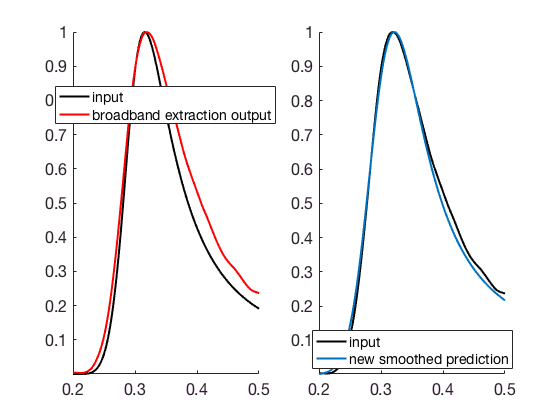

figure (1), clf
subplot(1, 2, 1)
plot(tTrial, dn_prd, 'k-', 'linewidth', 2), hold on
plot(tTrial, normMax(mean(signal.bbTrial, 2)), 'r-', 'linewidth', 2), box off
legend('input', 'broadband extraction output', 'Location', 'best'), set(gca, 'fontsize', 16), axis tight
xlim([0.2, 0.5])

subplot(1, 2, 2), cla
plot(tTrial, normMax(mean(signal.bbTrial, 2)), 'k-', 'linewidth', 2), hold on
plot(tTrial, smoothNewPrd, 'linewidth', 2), 
legend('input', 'new smoothed prediction', 'Location', 'best'), set(gca, 'fontsize', 16), 
axis tight, box off, xlim([0.2, 0.5])

## FIT A SMOOTH FUNCTION TO THE ORIGINAL DATA, AND RE-COMPUTE THE MODEL PARAMETERS

% GENERATE MODEL PREDICTIONS BASED ON THE PREVIOUS PARAMETERS
prd = [];

for iBoot = 1 : nBoots  
    ext_param     = [dn_prms(iBoot, 1), 0, dn_prms(iBoot, 2 : 5), 1];
    prd(iBoot, :) = dn_DNmodel(ext_param, stim, t);
end

prd = normMax(prd')';


## SMOOTH THE MODEL PREDICTION AND RE-FIT THE MODEL


for iBoot = 1 : nBoots
    exp_seed(iBoot, :) = [dn_seed(iBoot, :), 0];
    % smooth the data with a Gaussian kernal
    exp_data(iBoot, :) = conv(prd(iBoot, :), ker, 'same');
    % Fit the model searching for DN parameters
end

[prm, prd, r2, exitFlg] = dn_fineFit(exp_data, stim, t, ecogPrm, exp_seed, 'uniphasic');

dn_FineFit: 50
dn_FineFit: 100


dn_FineFit: 150


dn_FineFit: 200
dn_FineFit: 250
dn_FineFit: 300


dn_FineFit: 350


dn_FineFit: 400


## PLOT THE BEFORE AND AFTER PARAMETERS

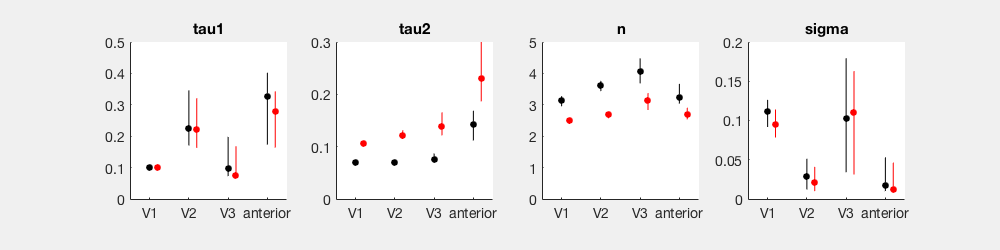

fg3 = figure (3); clf

for k = 1 : 4
    for iroi = 1 : 4
        idx = (iroi - 1) * 100 + 1 : iroi * 100;
        mprm(iroi) = median(prm(idx, k));
        sprm(iroi, :) = prctile(prm(idx, k), [25, 75]);
        
        mdn_prms(iroi) = median(dn_prms(idx, k));
        sdn_prms(iroi, :) = prctile(dn_prms(idx, k), [25, 75]);
        
    end
    subplot(1, 4, k)
    
    plot([1 : 4]+0.2, mprm, 'ro', 'markerfacecolor', 'r'), hold on
    plot(1 : 4, mdn_prms, 'ko', 'markerfacecolor', 'k')
    for k = 1 : 4
       plot([k, k] + 0.2, [sprm(k, :)], 'r-') 
       plot([k, k], sdn_prms(k, :), 'k-')
    end
    xlim([0.5, 4.5]), set(gca, 'xtick', 1 : 4, 'xticklabel', {'V1', 'V2', 'V3', 'anterior'}), 
    set(gca, 'fontsize', 14), axis square, box off
end
subplot(1, 4, 1), ylim([0, 0.5]), title('tau1')
subplot(1, 4, 2), ylim([0, 0.3]), title('tau2')
subplot(1, 4, 3), ylim([0, 5]), title('n')
subplot(1, 4, 4), ylim([0, 0.2]), title('sigma')

fg3.Position = [250, 1000, 1000, 250];

## COMPUTE THE DERIVED PARAMETERS

summaryMetrics2 = dn_computeDerivedParams(prm, 'uniphasic');

for iroi = 1 : 4
    idx = (iroi - 1) * 100 + 1 : iroi * 100;
    mt2pk1(iroi) = median(summaryMetrics.t2pk(idx));
    mt2pk2(iroi) = median(summaryMetrics2.t2pk(idx));
    
    st2pk1(iroi, :) = prctile(summaryMetrics.t2pk(idx), [25, 75]);
    st2pk2(iroi, :) = prctile(summaryMetrics2.t2pk(idx), [25, 75]);
    
    mrsaymp1(iroi) = median(summaryMetrics.r_asymp(idx));
    mrsaymp2(iroi) = median(summaryMetrics2.r_asymp(idx));
    
    srsaymp1(iroi, :) = prctile(summaryMetrics.r_asymp(idx), [25, 75]);
    srsaymp2(iroi, :) = prctile(summaryMetrics2.r_asymp(idx), [25, 75]);
end

## VISUALIZE

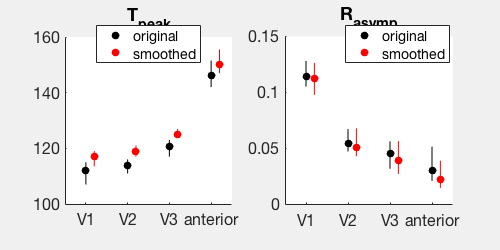

fg4 = figure (4); clf
subplot(1, 2, 1),
plot(1 : 4, mt2pk1, 'ko', 'markersize', 7, 'markerfacecolor', 'k'), hold on
plot(1.2 : 4.2, mt2pk2, 'ro', 'markersize', 7, 'markerfacecolor', 'r')
for iroi = 1 : 4
    plot([iroi, iroi], st2pk1(iroi, :), 'k-')
    plot([iroi, iroi]+0.2, st2pk2(iroi, :), 'r-')
end
xlim([0.5, 4.5]), legend('original', 'smoothed', 'Location', 'best'), box off
set(gca, 'fontsize', 16, 'xtick', 1 : 4, 'xticklabel', {'V1', 'V2', 'V3', 'anterior'}), title('T_{peak}')
axis square

subplot(1, 2, 2),
plot(1: 4, mrsaymp1, 'ko', 'markersize', 7, 'markerfacecolor', 'k'), hold on
plot(1.2 : 4.2, mrsaymp2, 'ro', 'markersize', 7, 'markerfacecolor', 'r')
for iroi = 1 : 4
    plot([iroi, iroi], srsaymp1(iroi, :), 'k-')
    plot([iroi, iroi]+0.2, srsaymp2(iroi, :), 'r-')
end
axis square
xlim([0.5, 4.5]), legend('original', 'smoothed', 'Location', 'best'), box off
set(gca, 'fontsize', 16, 'xtick', 1 : 4, 'xticklabel', {'V1', 'V2', 'V3', 'anterior'}), title('R_{asymp}')
fg4.Position = [250, 500, 500, 250];

## SAVE FIGURE

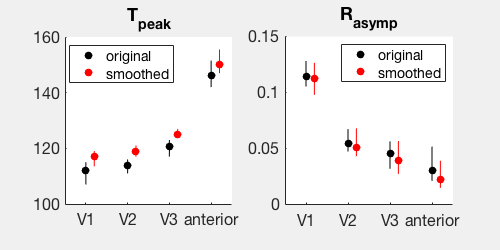

if saveFigure, 
    figLoc = fullfile(dn_ECoG_RootPath, 'analysisFigures');
    fg3Nm = 'fg_broadbandAssessment_A';
    printnice(3, 0, figLoc, fg3Nm);
    
    fg4Nm = 'fg_broadbandAssessment_B';
    printnice(4, 0, figLoc, fg4Nm);
end

## FUNCTIONS

function signal = extractbroadband(modelPrd, nSamples, nTrials, epochs, tAll, srate)
    
bands = [70 80; 80 90; 90 100; 100 110; 130 140; 140 150; 150 160; 160 170; 190 200; 200 210];

% disp(bands)

whiten         = @(x) (x - mean(x(:)))./ diff(prctile(x, [.25 .75]));
whiten_hilbert = @(x) abs(hilbert(whiten(x)));
normalize      = @(x) (x - mean(x([1 : 200, 1000 : end])))./max(x - mean(x([1 : 200, 1000 : end])));

modelPrd   = modelPrd + 1;
prdExd     = repmat(modelPrd', [1, nTrials, nSamples]);

signal.sim = poissrnd(prdExd, size(prdExd));

signal.raw = squeeze(reshape(signal.sim, [size(tAll), nSamples]));
if nSamples == 1, signal.raw = signal.raw'; end

% extract envelope of the signals;
signal.bp_multi = [];
for iSmp = 1 : nSamples
    for ii = 1 : size(bands, 1)
        signal.bp_multi(:,ii) = butterpass_eeglabdata(signal.raw(:, iSmp),bands(ii,:),srate);
    end
  %  size(signal.raw)
   signal.bb(:, iSmp) = sum(whiten_hilbert(signal.bp_multi),2);
   %size(signal.bb), size(epochs)
   signal.bbTrial(:, iSmp) = normalize(mean(reshape(signal.bb(:, iSmp), size(epochs)), 2));
end
end




